maxnum=0;minnum=0;
for i=1:4
    maxnum=max(maxnum,max(rms_all{i}(2:13,:),[],'all'));
end

for i=1:4
    rms_guiyi{i}=rms_all{i}(2:13,:);
end

单独绘图

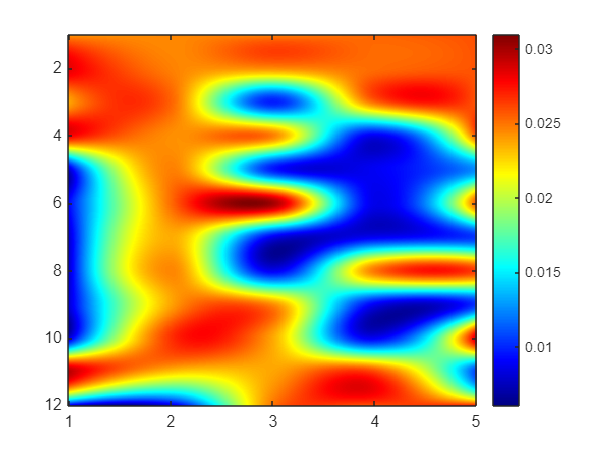

i=1;

iend=5;jend=12;step=0.01;
x=1:iend; y=1:jend; [x,y]=meshgrid(x,y);
x_i=1:step:iend;y_i=1:step:jend;
[xi,yi]=meshgrid(x_i,y_i);
zi=interp2(x,y,rms_guiyi{i},xi,yi,"cubic");
imagesc(x_i,y_i,zi);
colormap("jet")
colorbar

拼接

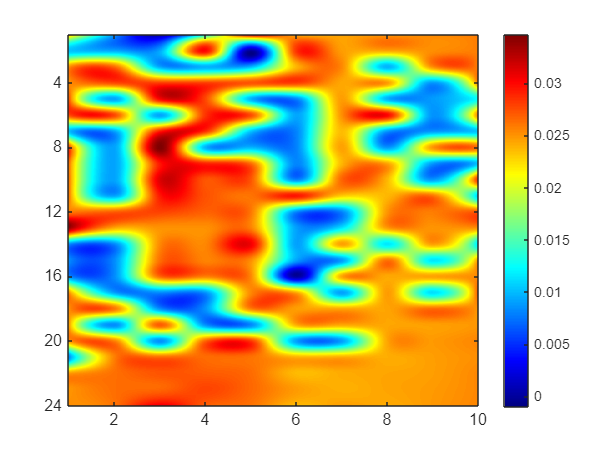

A=horzcat(rms_guiyi{4},rms_guiyi{1});
B=horzcat(rot90(rot90(rms_guiyi{2})),rot90(rot90(rms_guiyi{3})));
final=vertcat(A,B);
iend=10;jend=24;step=0.01;
x=1:iend; y=1:jend; [x,y]=meshgrid(x,y);
x_i=1:step:iend;y_i=1:step:jend;
[xi,yi]=meshgrid(x_i,y_i);
zi=interp2(x,y,final,xi,yi,"cubic");
imagesc(x_i,y_i,zi);
colormap("jet")
colorbar
xticks(2:2:10);
yticks(4:4:24)